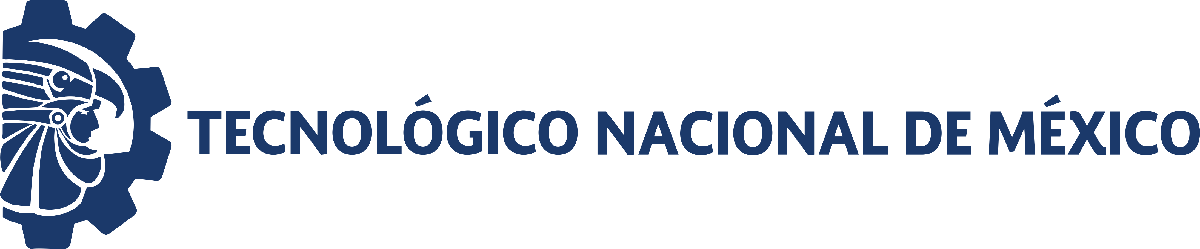                                 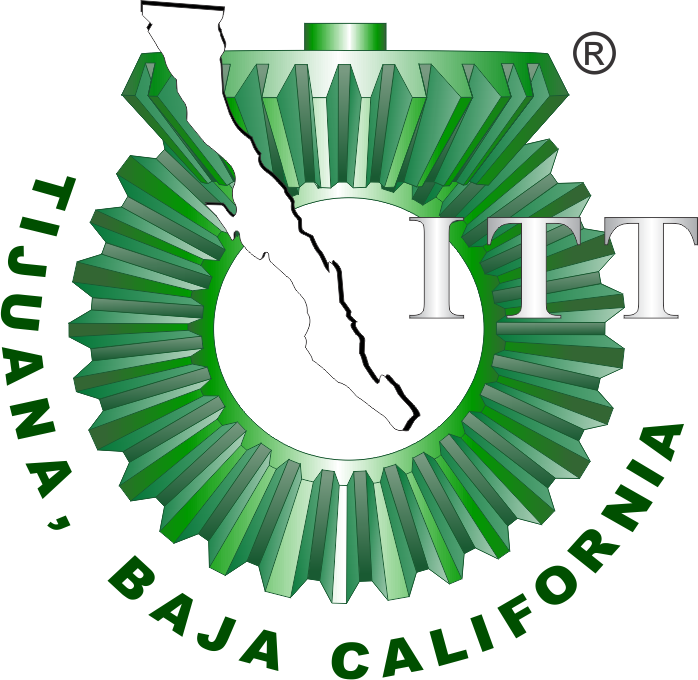

# Práctica 3: Sistema musculoesqueletico

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

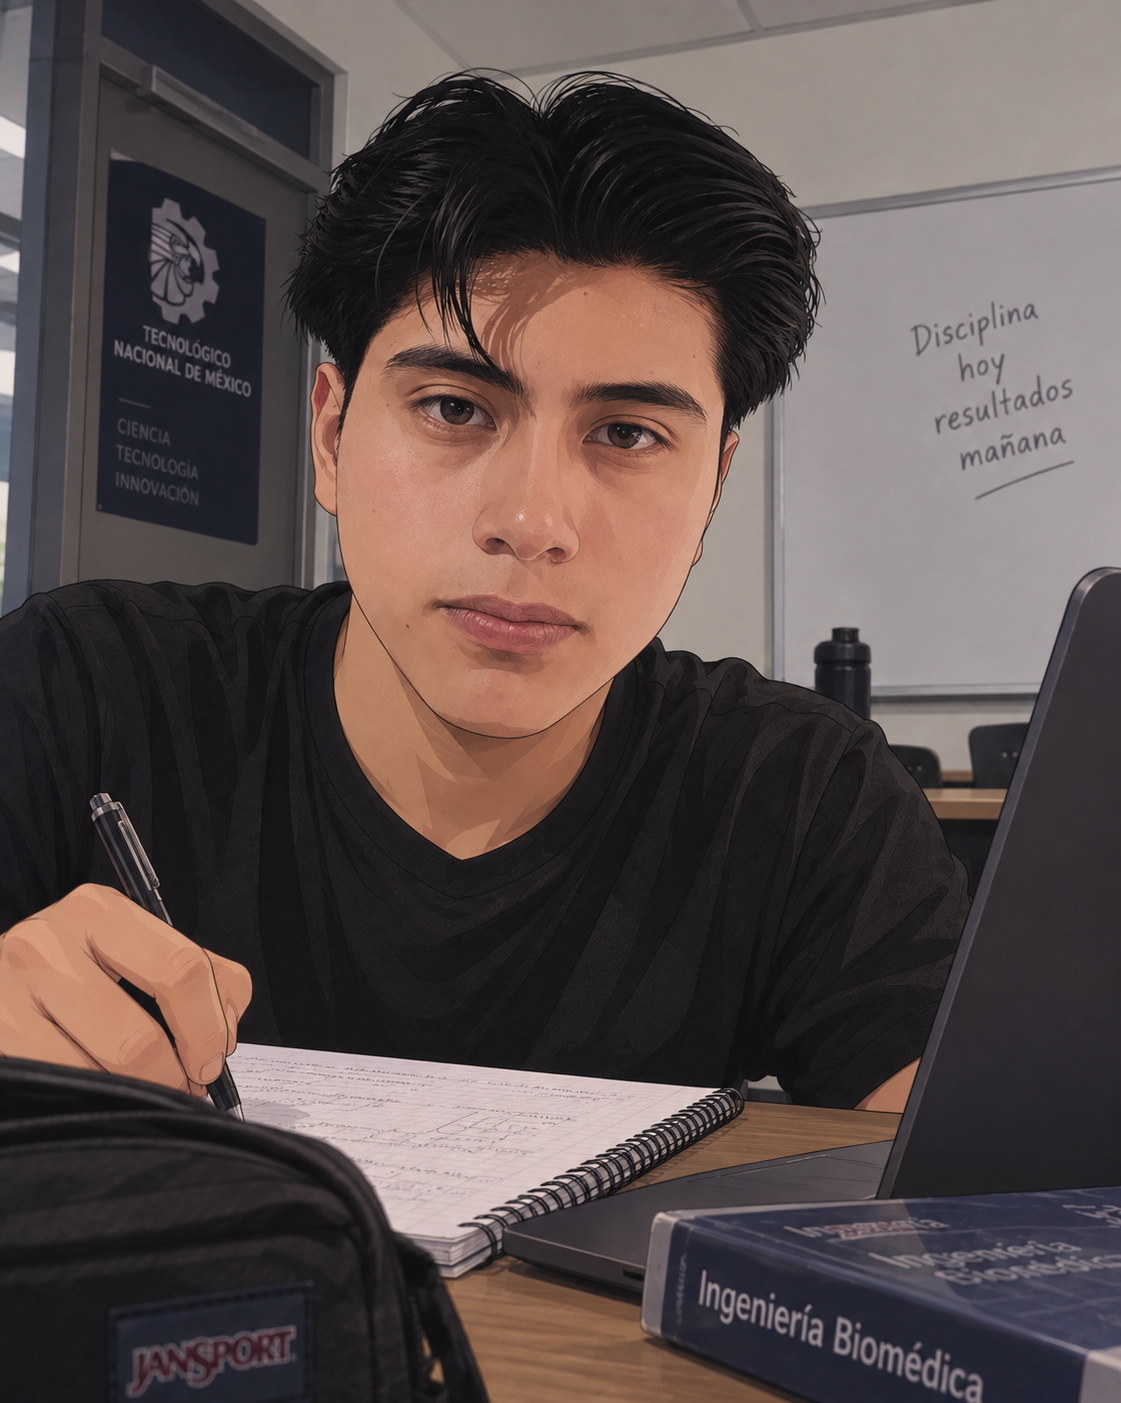

Nombre del alumno: Bautista Paz Jesus Geovanny

Número de control: 23212181

Correo institucional: l23212181**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('Sistemap3')
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
x = sim('Sistemap3',parameters);



## Respuesta:Control y caso

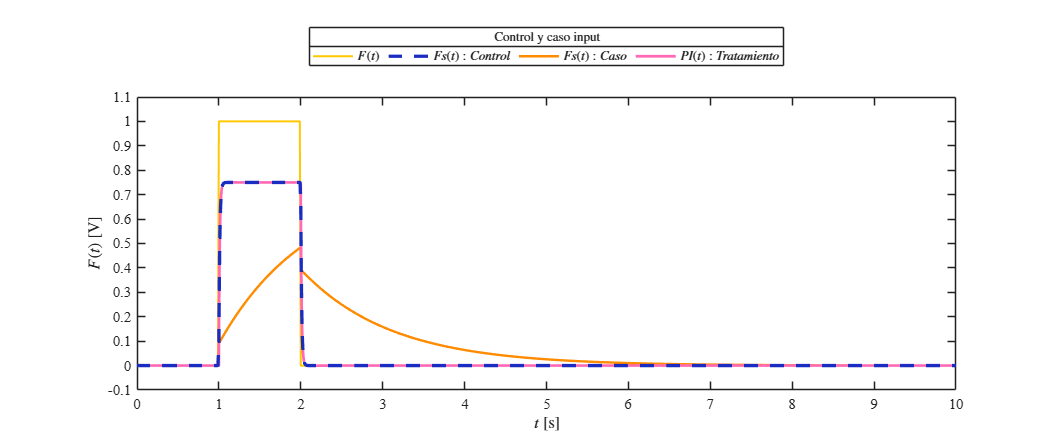



plotsignals(x.t,x.F,x.Fsx,x.Fsy,x.PID,'Control y caso')

## Funcion: Respuestas de la simulacion



function plotsignals(t,s,s1,s2,s3,signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,11,4.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;

    clr1 = [255,200,0]/255;    
    clr2 = [27,44,193]/255;    
    clr3 = [255,140,0]/255;    
    clr4 = [255,105,180]/255;  

    if signal == "Control y caso"
       
p1 = plot(t,s,'-','Color',clr1,'LineWidth',1.5);
p3 = plot(t,s2,'-','Color',clr3,'LineWidth',1.8);

p4 = plot(t,s3,'-','Color',clr4,'LineWidth',2);

p2 = plot(t,s1,'--','Color',clr2,'LineWidth',2.5);



        l = legend([p1(1),p2(1),p3(1),p4(1)], ...
            '$F(t)$', ...
            '$Fs(t): Control$', ...
            '$Fs(t): Caso$', ...
            '$PI(t): Tratamiento$');
    end

    set(l,'interpreter','latex', ...
          'location','northoutside', ...
          'orientation','horizontal')

    title(l,[signal,' input'])

    xlabel('$t$ [s]','interpreter','latex')
    ylabel('$F(t)$ [V]','interpreter','latex')

    xlim([0 10]); xticks(0:1:10)
    ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)

    exportgraphics(gcf,[signal,'.matlab.pdf'], ...
                   'contenttype','vector')
end
